clc;
close all;
clear variables;

out = evalc('kontroler_pracenje_reference');
clearvars -except K_pracenje_ref
[L, R, C, E, x2e] = nominalni_parametri();
[G, A, B, H, ue] = linearizacija();

G =
 
      2646.8 (s-606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



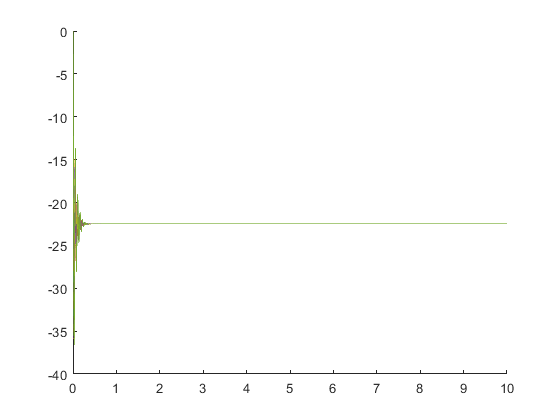

sim_file_name = 'robusnost_sim';
sim_duration = 1;
open_system(sim_file_name)
C_nom = C;
figure()
C_array = [0.8, 0.9, 1.0, 1.1, 1.2];
for i = 1:length(C_array)
    C = C_array(i)*C_nom;
    out = sim(sim_file_name);
    hold all;
    plot(out.V_C)
    
    
end